 LA DESTINAZIONE DEI FILE VA AGGIORNATA QUANDO CAMBI INTENSITA'
% LO SCRIPT CHIEDE NOME PER IL FILE (1-5) E SE SOVRASCRIVERE IN CASO DI NOME GIA' PRESENTE
clearvars;
clc;

global dataArray dataIndex fricezione tempdata tempIndex;

% durata acquisizione in secondi
durata = 60;

heartbeat_BLE(durata); % acquisisci dati

Connessione al dispositivo BLE "AA Pulse Oximeter"...
Dispositivo connesso!
Notifiche BLE abilitate.
Lettura per 60 secondi...
Acquisizione terminata.
Attendo ricezione asincrona temperatura (via callback)...
Totale campioni ricevuti: 5820
Frequenza media: 96.95 Hz
Totale temperature ricevute: 59


% Estrai il segnale e il tempo (escludendo eventuali posizioni vuote)
t_raw = dataArray(1:dataIndex-1, 1) / 1e6; % segnale t
t = t_raw - t_raw(1);  % tempo relativo che parte da 0
fprintf('Inizio t = %.2f s, Fine t = %.2f s, Durata = %.2f s\n', ...
         t(1), t(end), t(end) - t(1));

Inizio t = 0.00 s, Fine t = 60.03 s, Durata = 60.03 s


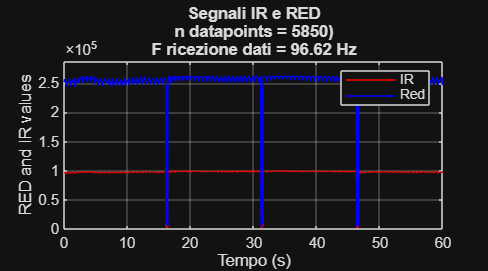



ir = dataArray(1:dataIndex-1, 2);       % segnale IR
red = dataArray(1:dataIndex-1, 3);      % segnale Red

% Estrai dati temperatura

% Estrai solo i dati con temperatura diversa da 0
valid_idx = tempdata(:,2) ~= 0;
temp_times_raw = tempdata(valid_idx, 1) / 1e3;
temp_vals = tempdata(valid_idx, 2);

% Allinea il tempo a sinistra (partenza da 0)
temp_times = temp_times_raw - temp_times_raw(1);


fs = fricezione; % frequenza di campionamento in Hz 

%% --- Plot dei segnali temporali ---
figSignals = figure('Name','Segnali IR e Red', 'Position', [100 100 900 500]);

% label info aggiuntive
labelDP = sprintf('n datapoints = %d)', length(t));
labelFS = sprintf('F ricezione dati = %.2f Hz', fs);

plot(t, ir, 'r', 'DisplayName','IR'); hold on;
plot(t, red, 'b', 'DisplayName','Red');

xlabel('Tempo (s)');
ylabel('RED and IR values');
legend('show');
title(sprintf('Segnali IR e RED\n%s\n%s', labelDP, labelFS));
grid on;
xlim([0 durata]);
signal_max = max([max(ir), max(red)]);
margin = 0.1 * signal_max;  % 10% margine sopra il massimo
ylim([0, signal_max + margin]);

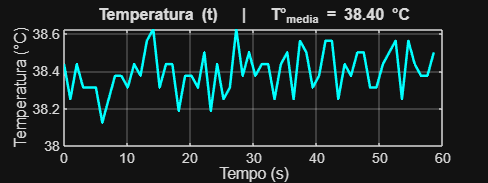


% Calcola la temperatura media 
mean_temp = mean(temp_vals);            % Calcola la media

% Figura temperatura
figTemp = figure('Name','Temperatura', 'Position', [100 550 800 300]);
plot(temp_times, temp_vals, 'c-', 'LineWidth', 1.5);
xlabel('Tempo (s)');
ylabel('Temperatura (°C)');
title(sprintf('Temperatura (t)   |   T°_{media} = %.2f °C', mean_temp));
grid on;
xlim([0 durata]);  

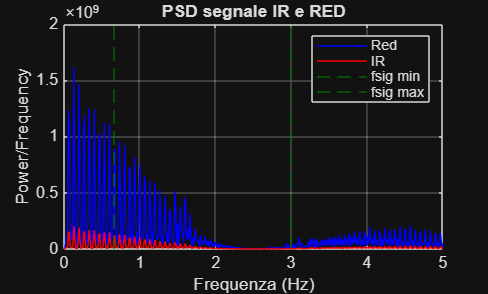


% Convertiamo range bpm in frequenze Hz:
bpm_low = 40;          % limite basso bpm
bpm_high = 180;        % limite alto bpm
f_low = bpm_low / 60;  % converti bpm in Hz 
f_high = bpm_high / 60;

%centro i segnali a zero
ir = ir - mean(ir);
red = red - mean(red);

% Calcolo PSD con periodogram 
[pxx_red, f_red] = periodogram(red, [], [], fs);
[pxx_ir, f_ir]   = periodogram(ir, [], [], fs);

% --- Plot delle PSD ---
figPSD = figure('Name','PSD IR e Red');
plot(f_red, pxx_red, 'b', 'DisplayName','Red'); hold on;
plot(f_ir, pxx_ir, 'r', 'DisplayName','IR');
h1 = xline(f_low, '--', 'Color', [0 0.5 0], 'DisplayName', 'fsig min'); 
h2 = xline(f_high, '--', 'Color', [0 0.5 0], 'DisplayName', 'fsig max');

h1.Label = '';
h2.Label = '';
xlabel('Frequenza (Hz)');
ylabel('Power/Frequency');
legend('show');
title('PSD segnale IR e RED');
xlim([0 5]);  % Mostra solo la banda di interesse
grid on;



% Calcolo potenza nel range 40-180 bpm (f_low-f_high Hz)
freq_mask_red = (f_red >= f_low) & (f_red <= f_high);
freq_mask_ir  = (f_ir  >= f_low) & (f_ir  <= f_high);

power_red_inband  = trapz(f_red(freq_mask_red), pxx_red(freq_mask_red));
power_red_outband = trapz(f_red(~freq_mask_red), pxx_red(~freq_mask_red));

power_ir_inband  = trapz(f_ir(freq_mask_ir), pxx_ir(freq_mask_ir));
power_ir_outband = trapz(f_ir(~freq_mask_ir), pxx_ir(~freq_mask_ir));

% Calcolo SNR come rapporto potenza in-band / potenza out-of-band
SNR_red = power_red_inband / power_red_outband;
SNR_ir = power_ir_inband / power_ir_outband;

% Trasformazione in decibel
SNR_red_dB = 10 * log10(SNR_red);
SNR_ir_dB = 10 * log10(SNR_ir);

% Stampa risultati
fprintf('Red Signal:\n');

Red Signal:


fprintf('Power in band (40-180 bpm): %.4f\n', power_red_inband);

Power in band (40-180 bpm): 232535206.1577


fprintf('Power out of band: %.4f\n', power_red_outband);

Power out of band: 1636239142.5983


fprintf('SNR: %.4f\n\n', SNR_red);

SNR: 0.1421




fprintf('IR Signal:\n');

IR Signal:


fprintf('Power in band (40-180 bpm): %.4f\n', power_ir_inband);

Power in band (40-180 bpm): 32496283.1145


fprintf('Power out of band: %.4f\n', power_ir_outband);

Power out of band: 228353342.2341


fprintf('SNR: %.4f\n', SNR_ir);

SNR: 0.1423



% SALVATAGGIO
fixedPath = 'C:\Users\ginev\Desktop\matlab\arduino\data\50mA';

% Chiedi il nome del file (senza estensione)
fileName = input('Inserisci il nome del file (senza estensione): ', 's');

if isempty(fileName)
    disp('Nome file non valido. Salvataggio annullato.');
else
    fullname = fullfile(fixedPath, [fileName, '.mat']);
    
    if exist(fullname, 'file') == 2
         % Chiedi conferma sovrascrittura
        answer = input(sprintf('Il file "%s" esiste già. Vuoi sovrascrivere? (s/n): ', fileName), 's');
        if strcmpi(answer, 's')
            save(fullname);
            fprintf('Workspace salvato in: %s\n', fullname);
        else
            disp('Salvataggio annullato dall’utente.');
        end
    else
         % File non esiste, salvo direttamente
        save(fullname);
        fprintf('Workspace salvato in: %s\n', fullname);
    end
 end

Workspace salvato in: C:\Users\ginev\Desktop\matlab\arduino\data\50mA\4.mat
